sam = segmentAnythingModel;

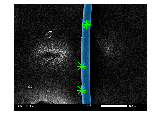


% 读取图像
inputFilePath = "/home/lzh/hair/hair_2025/2025_not_in_25_rename_need_reseg/" + ...
    "Tiger/Tiger_new tiger_back_93.Tif";
I = imread(inputFilePath);

% 获取图像尺寸
[height, width, ~] = size(I);

% 设置前景点0
%foregroundPoints = [1200,302;1600,301;1202,1729;1550,1828];
foregroundPoints = [700,200;650,832;650,600];
%foregroundPoints = [1300,434];
%foregroundPoints = [1350,434;1350,1500];
% 获取 embedding 并进行分割
embeddings = extractEmbeddings(sam, I);
[masks, scores, maskLogits] = segmentObjectsFromEmbeddings(sam, embeddings, [height, width], ...
    ForegroundPoints=foregroundPoints);

% 将掩码插入原图像
imMask = insertObjectMask(I, masks);
imshow(imMask);

% 显示前景点
fx = foregroundPoints(:, 1);
fy = foregroundPoints(:, 2);
hold on
plot(fx, fy, 'g*')
hold off

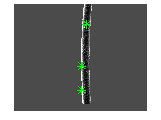


% 第二次分割，细化分割
refinedMasks = segmentObjectsFromEmbeddings(sam, embeddings, [height, width], ...
    ForegroundPoints=foregroundPoints, ...
    MaskLogits=maskLogits);  % 使用第一次分割的掩膜 logits 进行细化

% 创建灰色背景图像
grayBackgroundValue = 75; % 灰色值，取值范围为[0, 255]
grayBackgroundImage = grayBackgroundValue * ones(height, width, 'uint8'); % 创建灰色背景图像

% 将前景从原图复制到灰色背景图
outputImage = grayBackgroundImage; % 初始化为灰色背景
outputImage(refinedMasks) = I(refinedMasks); % 仅将前景插入灰色背景

% 显示结果图像
imshow(outputImage);

% 自动生成输出路径和文件夹
[~, fileName, ext] = fileparts(inputFilePath); % 提取文件名和扩展名
[inputDir, subDirName] = fileparts(fileparts(inputFilePath)); % 提取输入目录和子目录名称
outputBaseDir = "/home/lzh/hair/hair_2025/2025_not_in_25_rename_reseg_done"; % 输出基目录
outputSubDir = fullfile(outputBaseDir, subDirName); % 输出子目录路径
if ~exist(outputSubDir, 'dir')
    mkdir(outputSubDir); % 如果子目录不存在，则创建
end

outputFilePath = fullfile(outputSubDir,strcat(fileName, ext)); % 输出文件路径

% 保存结果图像
imwrite(outputImage, outputFilePath);

% 显示前景点
fx = foregroundPoints(:, 1);
fy = foregroundPoints(:, 2);
hold on
plot(fx, fy, 'g*') % 绿色星号标记前景点
hold off



% sam = segmentAnythingModel;
% 
% I = imread("/home/lzh/hair/hair_2025/85_need_reseg_ori/Asian_Badger/Asian_Badger_badger_202304_tail_zhong22.Tif");
% 
% % 获取图像尺寸
% [height, width, ~] = size(I);
% 
% % % 计算图像的中心点
% % centerX = floor(width / 2);
% % centerY = floor(height / 2);
% % 
% % % 计算上边界中点
% % topY = 1; % 上边界Y坐标
% % topPoint = [centerX, topY];
% % 
% % % 计算额外的前景点
% % extraPointY = floor(height * 0.935);
% % extraPoint = [centerX, extraPointY];
% % 
% % % 设置前景点和背景点
% % foregroundPoints = [centerX, centerY; topPoint; extraPoint];
% 
% foregroundPoints = [1141,932]
% 
% % 获取embedding并进行分割
% embeddings = extractEmbeddings(sam, I);
% [masks,scores,maskLogits] = segmentObjectsFromEmbeddings(sam, embeddings, [height, width], ...
%     ForegroundPoints=foregroundPoints);
% 
% % 将掩码插入原图像
% imMask = insertObjectMask(I, masks);
% imshow(imMask);
% 
% % 显示前景点和背景点
% fx = foregroundPoints(:, 1);
% fy = foregroundPoints(:, 2);
% hold on
% plot(fx, fy, 'g*')
% hold off
% 
% 
% % 第二次分割，细化分割
% refinedMasks = segmentObjectsFromEmbeddings(sam, embeddings, [height, width], ...
%     ForegroundPoints=foregroundPoints, ...
%     MaskLogits=maskLogits);  % 使用第一次分割的掩膜logits进行细化

% 
% % 创建灰色背景图像
% grayBackgroundValue = 75; % 灰色值，取值范围为[0, 255]
% grayBackgroundImage = grayBackgroundValue * ones(height, width, 'uint8'); % 创建灰色背景图像
% 
% % 将前景从原图复制到灰色背景图
% outputImage = grayBackgroundImage; % 初始化为灰色背景
% outputImage(refinedMasks) = I(refinedMasks); % 仅将前景插入灰色背景
% 
% % 显示结果图像
% imshow(outputImage);

% 
% % 可选：保存结果图像
% imwrite(outputImage, '/home/lzh/hair/hair_2025/reseg_done/Asian_Badger_badger_202304_tail_zhong22.Tif');
% 
% % 显示前景点
% fx = foregroundPoints(:, 1);
% fy = foregroundPoints(:, 2);
% 
% hold on
% plot(fx, fy, 'g*') % 绿色星号标记前景点
% hold off
% % % 将细化后的掩膜插入到原图像中
% % imMaskRefined = insertObjectMask(I, refinedMasks);
% % imshow(imMaskRefined);
% % 
% % % 显示前景点和背景点
% % fx = foregroundPoints(:, 1);
% % fy = foregroundPoints(:, 2);
% % 
% % hold on
% % plot(fx, fy, 'g*')
% % hold off
